In this onboarding you will build both a physical simscape model and a Linear Quadratic Regulator (LQR) controller for a cart-pole system

You will first construct the cart-pole as a physical system using Simscape Multibody. You will then develop a mathematical model of the system in MATLAB and use this model to design an LQR controller. Finally, you will implement the controller in Simulink and test it against the Simscape model.

The purpose of this project is to learn the full toolchain from system modeling to simulation,

remember, if you struggle with anything there are usually hints, or you can come to me during controls or general meetings for assistance. it may also be worth asking other people who are doing the onboardings for their advice.

This is a diagram of the system:

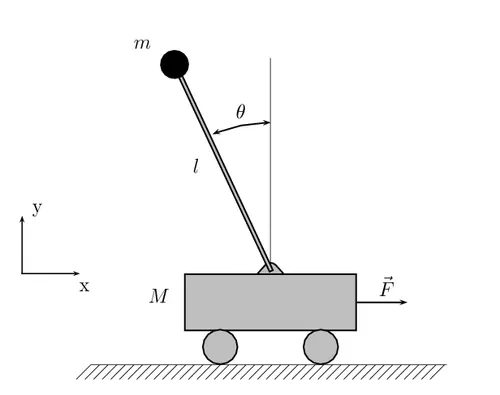

with these variable conventions:

the goal is to keep the inverted pendulum upright while controlling the position of the cart

The pendulum is inherently unstable. If the pendulum is displaced from its upright position, gravity causes it to fall. The controller must therefore continuously move the cart to keep the pendulum balanced.

### Task 1:

create a simulink model and add the required blocks:

you should set up these blocks in a way that allows the cart to move along the world x axis on the prismatic joint and allows the rod to rotate around the world y axis while attached to the cart. you will need to use Rigid Transform blocks to ensure the joints are oriented correctly and that the solids are positioned correctly

Then enable sensing for position and velocity for both the Prismatic and Revolute joints to ensure that the conventions are correct and it behaves as expected, you will probably need to add some ps->simulink converter blocks and some scopes. i reccomend setting it up so the pendulum is initially vertical as this will allow you to not need to do much with the sensor values to get the correct reading. if it is vertical though it can take a long time for it to fall over though, in fact it may never. this is why we will give our system an initial push, to do this, and eventually add a force from the control system, we will add an External Force/Torque block and connect it to the cart frame, we can then set the force to go along the carts axis and connect that to something that applies a force for a small time and then stops

this is an example of how to make that:

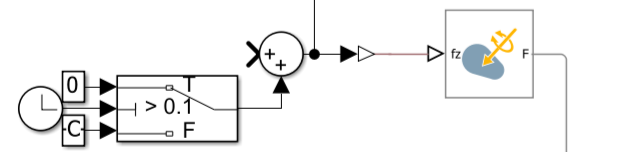

Hint 1 contains the completed multibody if you cannot figure it out.

### Task 2:

now that we can measure the states of the system, we should compile those into a state vector:

x_vec = [x x_dot theta theta_dot]

Using the cart-pole diagram and the variable definitions above, derive the nonlinear equations of motion for the system.

Your equations should describe: x_ddot and theta_ddot

as functions of:

x_vec ie [x x_dot theta theta_dot] and the input F which is the force applied to the cart

note that they will not necessarily be the same as any you find online as our rod has a different moment of inertia than most derivations that use a point mass or line mass

If you have taken a dynamics course this step should be self explanatory, if you have not, hint 2 goes in depth on the derivations and as this system is suprisingly complex due to its interconnectedness it may be helpful to use the hint as a guide.

Once you have these equations, implement them in matlab as a function:

function x_vec_dot = dynamics(x_vec, F)

make sure that all constants are the same as you have put into the simscape model and that you properly calculate the rods moment of inertia.

If you are struggling with this, hint 3 contains the completed dynamics

It is worth validating your model against the simscape one, this can be done programatically by using matlabs ode45 function, and comparing results, or just by putting that matlab function in a simulink function block and comparing resulting graphs. if they dont match, try to debug it yourself, make sure that initial conditions and physical parameters are the same.

### Task 3

now that we have nonlinear dynamics we need to convert these into a linear representation around our control point.

a simple way to do this is using the jacobian, you can either compute this by hand or have matlab help by using the symbolic math toolbox.

i do it by matlab but if you want a challenge then go ahead and hand derive.

in order to use symbolic math you must first create a script and define all the variables as symbolic variables using

syms pos vel theta omega real

syms F_in real

syms M m l r lc g real

you can then rewrite the dynamics using these variables and finally instead of returning x_dot, you can compute jacobians  A = x_dot with respect to x (the state) and B=  x_dot with respect to F (the input) using

jacobian(x_dot,_)

 , then you can use the subs function to substitute in the parameters for M m l r lc and g, and then you can substitute in the equilibrium as well, for our case the equilibrium is [0 0 0 0] and F = 0, as positions and angles are all zero when the cart is centered and the angle is straight up and there is no velocities nor force on the cart.

after substituting in the parameters and the equilibrium we get A0 and B0 which can be used in the matlab lqr function to compute the gain matrix for our controller.

K = lqr(A0,B0,diag([1,0,1,0]),[1])

this function is quite complex and if you want to learn more about it i recommend the matlab documentation and youtube tutorials, but essentially the first two inputs are just the dynamics, the third one (what is known as the Q matrix or state-cost weighted matrix) is what the controller prioritizes stabilizing, and the fourth one is the R matrix, or Input cost weighted matrix, which is what inputs the controller prioritizes using, for this case our only input is force on the cart which means we can just leave it at 1, but in more complex examples this allows us to adjust what inputs the controller tries to use more to stabilize.

the Q matrix

the output of this function is the gain matrix K, which essentially transforms the current state vector into the required input vector that causes a state change that forces the system back to stability.

### Task 4

now that we have our gain matrix, we can connect all our sensor values to a mux to combine them into a state vector, multiply that by K by using a gain block, and then we can route this back into the force, using a sum block to combine this with the initial push force.

If everything is correct then it should be able to stabilize, otherwise common issues include incorrect sizes or masses of objects, sign errors, or incorrect conventions about direction or rotation, i recommend double checking all of those.